1.Load and Extract Text Data

% Load the example data
data = readtable("proc_data_row.csv",'TextType','string');
head(data)
% Extract the text data from the field event_narrative

ans = 8×5 table
    Var1           no           month    day                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            

textData = data.content;
textData(1:10)

2.Prepare Text Data for Analysis 

% Use the example preprocessing function

ans = 10×1 string 数组
    "“ 扶 一把 老百姓 ” （ 人民 论坛 ） “ 我们 这代人 有 一份 情结 ， 扶 一把 老百姓 特别 是 农民 。 社会主义 道路 上 一个 也 不能 少 ， 全面 小康 大家 一起 走 ！ ” 在 看望 参加 全国政协 十三届 三次 会议 的 经济界 委员 时 ， 习近平 总书记 回顾 自己 在 陕北 黄土地 上 的 贫苦 日子 和 青葱 岁月 ， “ 扶 一把 老百姓 ” 的 真挚 情怀 ， 让 人 感动 ， 更 发人 思考 。 过去 一年多来 ， “ 中国 号 ” 巨轮 风雨无阻 的 航程 中 ， 万家 忧乐 、 百姓 冷暖 ， 始终 是 党和政府 念兹在兹 的 中心 议题 。 2019 年 ， 农村 贫困人口 减少 1109 万 ， 居民 人均 可 支配 收入 超过 3 万元 ， “ 扶 一把 老百姓 ” ， 书写 于 充满 温度 的 民生 故事 ； 疫情 防控 中 ， 上 至 108 岁 的 老人 ， 下 至 出生 仅 30 个 小时 的 婴儿 ， 我们 不 放弃 任何 一名 患者 ， “ 扶 一把 老百姓 ” ， 彰显 于 震撼 世界 的 生命 奇迹 。 亿万人民 满满的 获得 感 、 稳稳 的 幸福感 、 牢牢 的 安全感 ， 体现 了 我们 党 “ 全心全意 为 人民 服务 ” 的 根本宗旨 ， 承载 着 我们 党 “ 以 人民 为 中心 ” 的 发展 思想 。 “ 扶 一把 老百姓 ” ， 就是 把 老百姓 时刻 放在 心中 ， 以 百姓 之心 为 心 。 “ 政如 农功 ， 日夜 思之 ” 。 植根于 农业 社会 ， 中国 传统 政治 思想 中 ， 对于 治理 最 强调 “ 用心 ” “ 上 心 ” 。 耕种 土地 ， 需要 精心 管护 、 日夜操劳 ， 才能 有 秋收 万斛 、 仓廪充实 。 为政者 也 要 如此 ， 朝暮 心系 于民 、 事事 行之 为民 ， 才能 做到 “ 为官一任 ， 造福一方 ” 。 对于 共产党人 ， 什么 叫 “ 老百姓 是 天 ， 老百姓 是 地 ” ， 什么 叫 “ 把 人民 放在 心中 最高 位置 ” ？ 就是 要 始终保持 “ 时时 放心不下 ” 的 自觉 ， 始终 怀有 “ 扶 一把 老百姓 ” 的 情怀 ， 用 实际行动 让 人民 信赖 、 让 人

% preprocessWeatherNarratives
% to prepare the text data.
documents = preprocessRMRB(textData);
documents(1:5)


3.Cloud

figure
labels = data.month;

ans =   5×1 tokenizedDocument:

     259 tokens: 百姓 人民 论坛 这代 百姓 农民 社会 道路 不能 全面 小康 大家 一起 参加 国政 经济 习近 总书 自己 陕北 黄土 贫苦 日子 岁月 百姓 发人 思考 过去 中国 巨轮 风雨 无阻 忧乐 百姓 政府 兹在 中心 议题 2019 农村 贫困 人口 减少 1109 支配 百姓 书写 温度 民生 故事 疫情 108 老人 出生 30 婴儿 患者 百姓 震撼 世界 生命 亿万 人民 满满 获得 稳稳 幸福 安全 人民 根本 宗旨 人民 中心 发展 思想 百姓 就是 百姓 时刻 心中 百姓 农功 思之 农业 社会 中国 传统 政治 思想 对于 强调 用心 土地 需要 日夜 才能 万斛 仓廪 为政 如此 朝暮 于民 事事 为民 才能 做到 为官 一任 一方 对于 产党 什么 百姓 百姓 什么 人民 心中 最高 位置 就是 保持 时时 放心 怀有 百姓 实际 人民 人民 满意 肚子 净颗 细粮 细粮 经常 挑着 扁担 习近 总书 谈起 几个 说明 这样 观点 保障 改善 民生 终点 连续 不断 起点 问题 全面 小康 胜利 放心 健康 人民 美好 生活 不断 攀升 需要 民生 改善 进一 百姓 百姓 具体 百姓 日子 幸福 百姓 实实 良心 需用 真心 需见 决战 决胜 剩下 硬骨 叠加 疫情 难上 集中 精力 以保 促稳 稳中 发展 需要 民生 需要 就业 900 减税 费约 5000 亿元 不足 农民 纳入 常住 保障 新建 标准 农田 8000 今年 政府 工作 报告 系列 民生 举措 见证 大国 民生 牵挂 激励 级党 政府 民生 工作 真正 百姓 变成 实际 天下 天下 天下 天下 赢得 疫情 胜利 还是 如期 全面 小康 社会 根本 动力 人民 百姓 民心 民力 亿万 人民 劲往 一定 战胜 一切 艰难 险阻 书写 无愧 时代 无愧 历史
    1108 tokens: 推动 社会 核心 价值 家庭 落地 以来 习近 总书 国家 发展 全局 促进 全面 发展 家庭 家教 发表 系列 重要 讲话 强调 家庭 家教 家

subplot(1,4,1)
idx = labels == 1;
wordcloud(documents(idx),'Color','blue','Shape','rectangle','Box','on');
title("一月")
subplot(1,4,2)
idx = labels == 2;
wordcloud(documents(idx),'Color','red', 'Shape','rectangle','Box','on');
title("二月")
subplot(1,4,3)
idx = labels == 3;
wordcloud(documents(idx),'Color','magenta','Shape','rectangle','Box','on');
title("三月")
subplot(1,4,4)
idx = labels == 4;
wordcloud(documents(idx),'Shape','rectangle','Box','on');
title("四月")

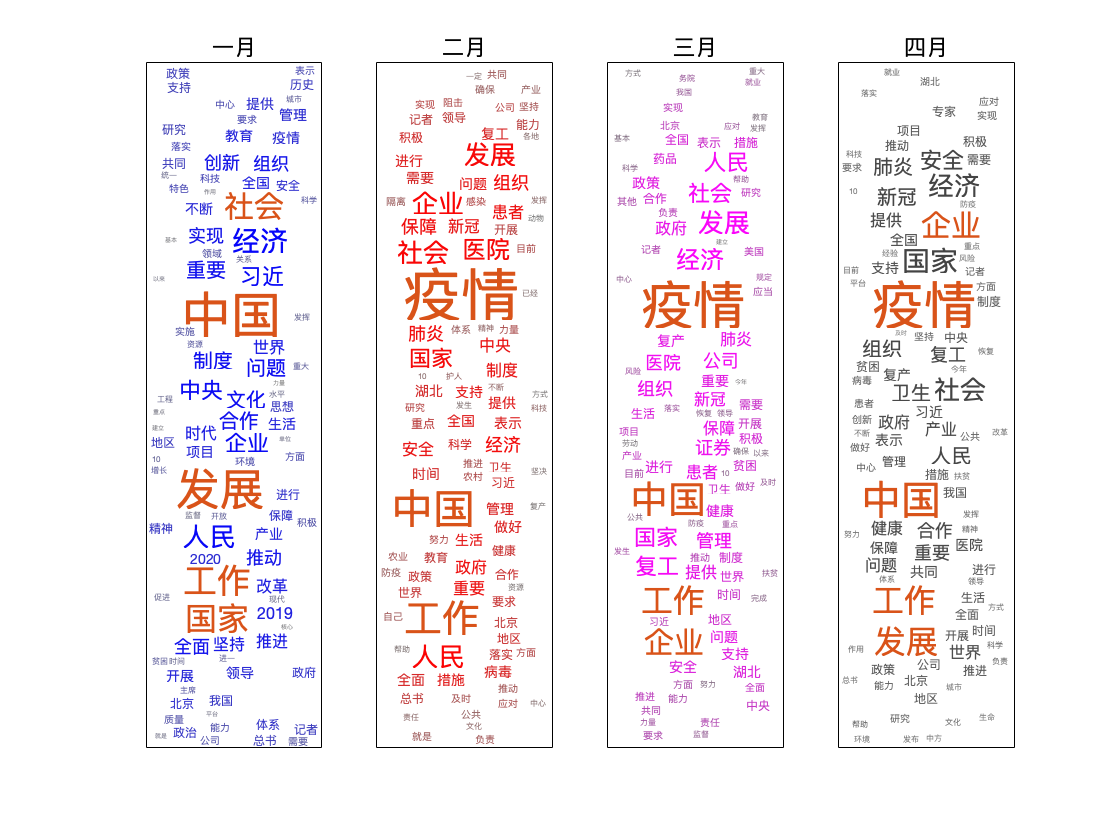

figure
labels = data.month;
subplot(1,4,1)
idx = labels == 5;
wordcloud(documents(idx),'Color','blue','Shape','rectangle','Box','on');

title("五月")
subplot(1,4,2)
idx = labels == 6;
wordcloud(documents(idx),'Color','red', 'Shape','rectangle','Box','on');
title("六月")
subplot(1,4,3)
idx = labels == 7;
wordcloud(documents(idx),'Color','magenta','Shape','rectangle','Box','on');
title("七月")
subplot(1,4,4)
idx = labels == 8;
wordcloud(documents(idx),'Shape','rectangle','Box','on');
title("八月")

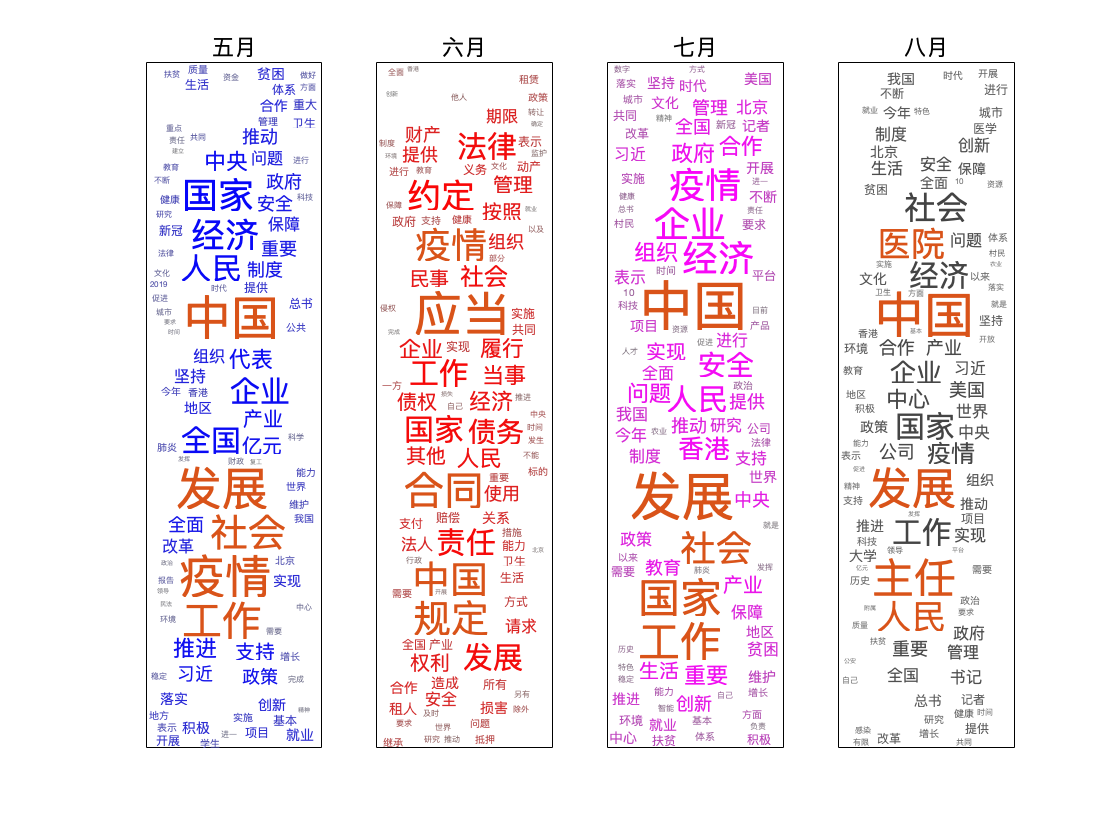

figure
labels = data.month;
subplot(1,4,1)
idx = labels == 9;
wordcloud(documents(idx),'Color','blue','Shape','rectangle','Box','on');
title("九月")

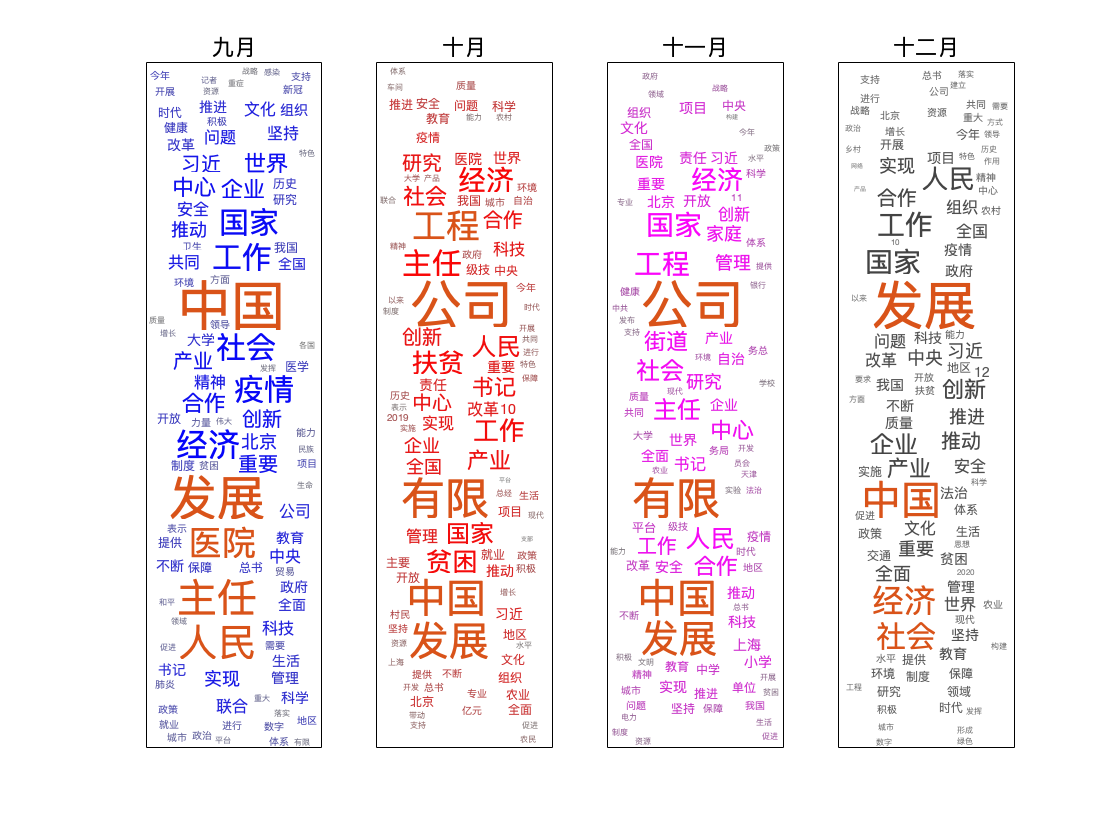

subplot(1,4,2)
idx = labels == 10;
wordcloud(documents(idx),'Color','red', 'Shape','rectangle','Box','on');
title("十月")
subplot(1,4,3)
idx = labels == 11;
wordcloud(documents(idx),'Color','magenta','Shape','rectangle','Box','on');
title("十一月")
subplot(1,4,4)
idx = labels == 12;
wordcloud(documents(idx),'Shape','rectangle','Box','on');
title("十二月")